close all; clear; clc;

# P80 4 battery full runs  (5, 10, and 20 min)

**file name**: 

**keywords:** 

**date of test:** 20181106/20181101

**file created by:** 20190306, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3] 
% Record this in the notes section above

% Rotor Specs
radius = 13.5/12;               % [ft] This was the 27 in..right??
area = pi * radius^(2);       % [ft^2]

## Measured Data -- 20 min

load('P80_4bat_20min_20181106.mat');
time20 = P80_4bat_20min_20181106(:,1);                       % [sec]
PWM20 = P80_4bat_20min_20181106(:,2);                        % [micro sec]
Q20 = P80_4bat_20min_20181106(:,4);                          % [ft.lbf]
T20 = P80_4bat_20min_20181106(:,5);                          % [lbf]
Input_V20 = P80_4bat_20min_20181106(:,6);                    % [Volts]
Input_A20 = P80_4bat_20min_20181106(:,7);                    % [Amps]
rot_speed_rpm20 = P80_4bat_20min_20181106(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad20 = rot_speed_rpm20 .* (pi/30);   % [rad/sec]
P_in_W20 = P80_4bat_20min_20181106(:,9);                     % [Watts]
P_out_W20 = P80_4bat_20min_20181106(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out20 = P_out_W20 .* 0.7478;                  % [ft.lbf/sec]         
P_in20 = P_in_W20 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff20 = P80_4bat_20min_20181106(:,11);                 % [%]
Prop_Eff20 = P80_4bat_20min_20181106(:,12);                  % [lbf/Watts]
Overall_Eff20 = P80_4bat_20min_20181106(:,13);               % [lbf/Watts]  
ESC_Temp20 = P80_4bat_20min_20181106(:,14);                  % [F]
Motor_Temp20 = P80_4bat_20min_20181106(:,15);                % [F]

disk_loading20 = T20 ./ area;                     % [lb/sq.ft]
time_m20 = time20 ./ 60;

Max_motor_temp_20min = max(Motor_Temp20)

Max_motor_temp_20min = 103.7750


throttle20 = (PWM20 - 1000) ./ 10;


## Measured Data -- 10 min

load('P80_4bat_10min_20181106.mat');
time10 = P80_4bat_10min_20181106(:,1);                       % [sec]
PWM10 = P80_4bat_10min_20181106(:,2);                        % [micro sec]
Q10 = P80_4bat_10min_20181106(:,4);                          % [ft.lbf]
T10 = P80_4bat_10min_20181106(:,5);                          % [lbf]
Input_V10 = P80_4bat_10min_20181106(:,6);                    % [Volts]
Input_A10 = P80_4bat_10min_20181106(:,7);                    % [Amps]
rot_speed_rpm10 = P80_4bat_10min_20181106(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad10 = rot_speed_rpm10 .* (pi/30);   % [rad/sec]
P_in_W10 = P80_4bat_10min_20181106(:,9);                     % [Watts]
P_out_W10 = P80_4bat_10min_20181106(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out10 = P_out_W10 .* 0.7478;                  % [ft.lbf/sec]         
P_in10 = P_in_W10 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff10 = P80_4bat_10min_20181106(:,11);                 % [%]
Prop_Eff10 = P80_4bat_10min_20181106(:,12);                  % [lbf/Watts]
Overall_Eff10 = P80_4bat_10min_20181106(:,13);               % [lbf/Watts]  
ESC_Temp10 = P80_4bat_10min_20181106(:,14);                  % [F]
Motor_Temp10 = P80_4bat_10min_20181106(:,15);                % [F]

disk_loading10 = T10 ./ area;                     % [lb/sq.ft]
time_m10 = time10 ./ 60;

Max_motor_temp_10min = max(Motor_Temp10)

Max_motor_temp_10min = 108.5000


throttle10 = (PWM10 - 1000) ./ 10;


## Measured Data -- 5 min

load('P80_4bat_5min_20181101.mat');
time5 = P80_4bat_5min_20181101(:,1);                       % [sec]
PWM5 = P80_4bat_5min_20181101(:,2);                        % [micro sec]
Q5 = P80_4bat_5min_20181101(:,4);                          % [ft.lbf]
T5 = P80_4bat_5min_20181101(:,5);                          % [lbf]
Input_V5 = P80_4bat_5min_20181101(:,6);                    % [Volts]
Input_A5 = P80_4bat_5min_20181101(:,7);                    % [Amps]
rot_speed_rpm5 = P80_4bat_5min_20181101(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad5 = rot_speed_rpm5 .* (pi/30);   % [rad/sec]
P_in_W5 = P80_4bat_5min_20181101(:,9);                     % [Watts]
P_out_W5 = P80_4bat_5min_20181101(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out5 = P_out_W5 .* 0.7478;                  % [ft.lbf/sec]         
P_in5 = P_in_W5 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff5 = P80_4bat_5min_20181101(:,11);                 % [%]
Prop_Eff5 = P80_4bat_5min_20181101(:,12);                  % [lbf/Watts]
Overall_Eff5 = P80_4bat_5min_20181101(:,13);               % [lbf/Watts]  
ESC_Temp5 = P80_4bat_5min_20181101(:,14);                  % [F]
Motor_Temp5 = P80_4bat_5min_20181101(:,15);                % [F]

disk_loading5 = T5 ./ area;                     % [lb/sq.ft]
time_m5 = time5 ./ 60;

Max_motor_temp_5min = max(Motor_Temp5)

Max_motor_temp_5min = 106.9250


throttle5 = (PWM5 - 1000) ./ 10;


## Plots

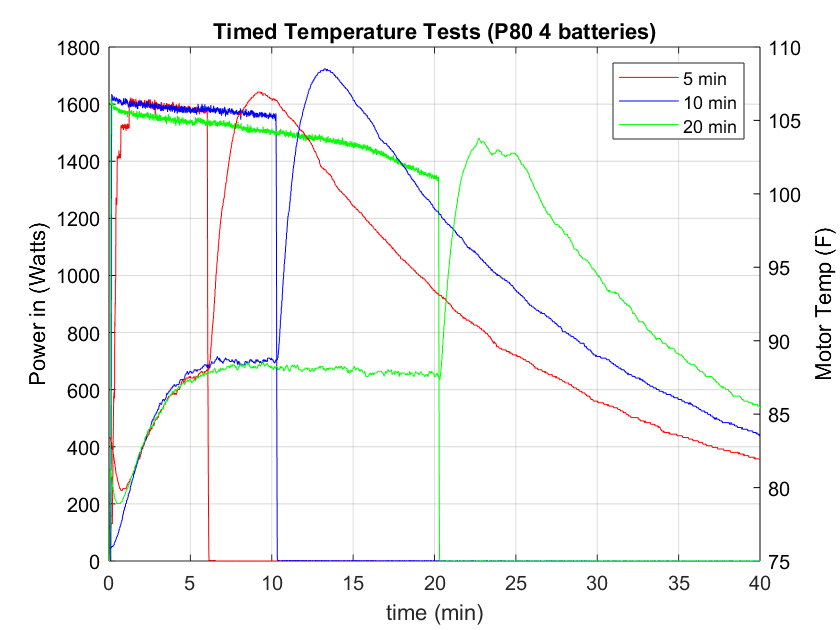

figure4 = figure('Color',[1 1 1]);
axes4 = axes('Parent',figure4);
yyaxis left;
plot(time_m5(3:end), P_in_W5(3:end), '-r', ...
    time_m10(3:end), P_in_W10(3:end), '-b', ...
    time_m20(3:end), P_in_W20(3:end), '-g'); 
grid on; box on;
xlabel('time (min)');
ylabel('Power in (Watts)','Color','k');
set(axes4,{'ycolor'},{'k'});
yyaxis right;
plot(time_m5(3:end), Motor_Temp5(3:end), '-r',...
    time_m10(3:end), Motor_Temp10(3:end), '-b',...
    time_m20(3:end), Motor_Temp20(3:end), '-g'); 
grid on; box on;
xlabel('time (min)');
xlim([0 40]);
ylabel('Motor Temp (F)','Color','k');
set(axes4,{'ycolor'},{'k'});
title('Timed Temperature Tests (P80 4 batteries)');
legend('5 min','10 min', '20 min');

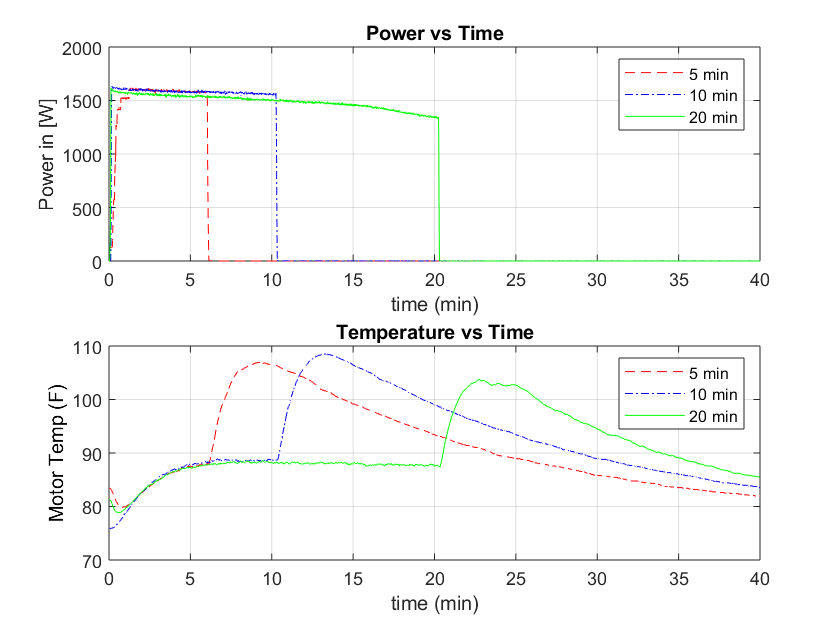


figure(40)
title('Timed Temperature Tests (P80 4 batteries)');
subplot(2,1,1)
plot(time_m5(3:end), P_in_W5(3:end), '--r', ...
    time_m10(3:end), P_in_W10(3:end), '-.b', ...
    time_m20(3:end), P_in_W20(3:end), '-g');
title('Power vs Time');
grid on; box on;
xlabel('time (min)');
ylabel('Power in [W]')
xlim([0 40]);
legend('5 min','10 min', '20 min');
subplot(2,1,2)
plot(time_m5(3:end), Motor_Temp5(3:end), '--r',...
    time_m10(3:end), Motor_Temp10(3:end), '-.b',...
    time_m20(3:end), Motor_Temp20(3:end), '-g');
grid on; box on;
xlabel('time (min)');
xlim([0 40]);
ylabel('Motor Temp (F)','Color','k');
title('Temperature vs Time');
legend('5 min','10 min', '20 min');

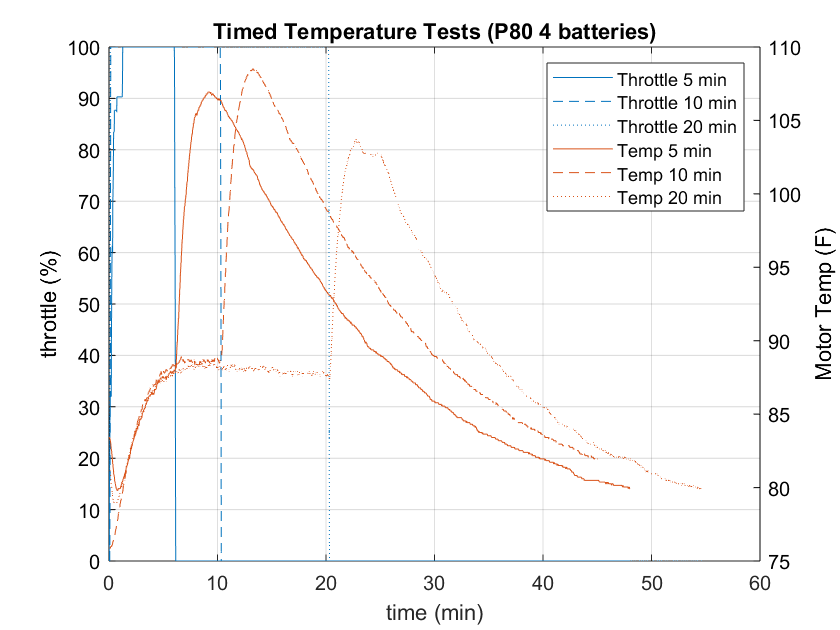



figure7 = figure('Color',[1 1 1]);
axes7 = axes('Parent',figure7);
yyaxis left;
plot(time_m5(3:end), throttle5(3:end), ...
    time_m10(3:end), throttle10(3:end),...
    time_m20(3:end), throttle20(3:end)); 
grid on; box on;
xlabel('time (min)');
ylabel('throttle (%)','Color','k');
set(axes7,{'ycolor'},{'k'});
yyaxis right;
plot(time_m5(3:end), Motor_Temp5(3:end),...
    time_m10(3:end), Motor_Temp10(3:end),...
    time_m20(3:end), Motor_Temp20(3:end)); 
grid on; box on;
xlabel('time (min)');
ylabel('Motor Temp (F)','Color','k');
set(axes7,{'ycolor'},{'k'});
title('Timed Temperature Tests (P80 4 batteries)');
legend('Throttle 5 min','Throttle 10 min', 'Throttle 20 min',...
    'Temp 5 min', 'Temp 10 min', 'Temp 20 min');